modelfile = "UNet_Final_testv3_nl_minmax.h5";
net = importKerasNetwork(modelfile);

analyzeNetwork(net);

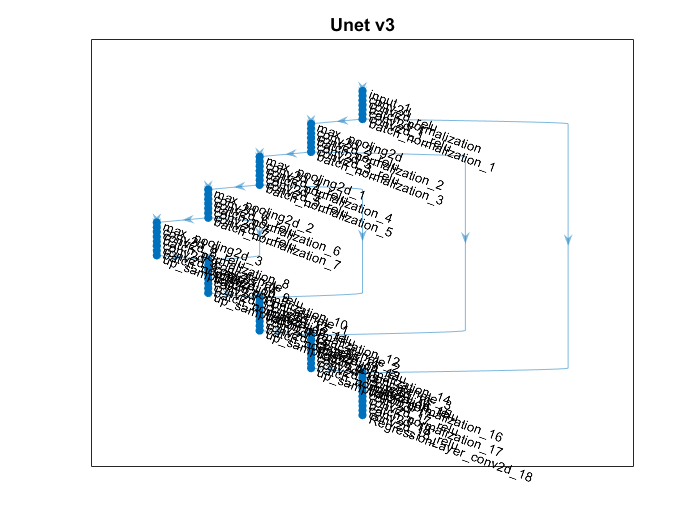

plot(net);
title('Unet v3');

x = load('X.mat');
y = load('Y.mat');



x = struct2cell(x);
y = struct2cell(y);
x = cell2mat(x);
y = cell2mat(y);

input = normalize(x(:,:,2200),'range',[0 1])

input =     0.9213    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.0254    0.0249    0.0247    0.0244    0.0246    0.0257    0.0274    0.0287    0.0286    0.0278    0.0271    0.0282    0.0305    0.0328    0.0345    0.0350    0.0364    0.0411    0.0499    0.0591    0.0649    0.0666    0.0668    0.0683    0.0717    0.0759    0.0799    0.0832    0.0863    0.0900    0.0949    0.1007    0.1064    0.1115    0.1162    0.1204    0.1243    0.1286    0.1308    0.1274    0.1174    0.1058    0.0977    0.0942    0.0913    0.0850    0.0726    0.0585    0.0486 

output = predict(net,input)

output = 400×400 single matrix
    0.7847    0.9899    0.9507    0.9575    0.9649    0.9790    0.9986    1.0050    1.0037    1.0012    1.0002    1.0003    1.0030    0.9957    1.0000    1.0043    1.0206    1.0098    1.0079    1.0102    1.0205    1.0113    1.0085    1.0187    1.0254    1.0207    1.0146    1.0282    1.0246    1.0155    1.0056    1.0123    1.0137    1.0064    1.0129    1.0181    1.0212    1.0172    1.0184    1.0061    0.9967    0.9997    1.0056    0.9908    0.9883    1.0066    1.0171    1.0120    1.0095    1.0287
    0.0901    0.0559         0         0         0         0         0    0.0105    0.0238    0.0221    0.0193    0.0161    0.0209    0.0242    0.0227    0.0261    0.0452    0.0586    0.0518    0.0576    0.0688    0.0707    0.0665    0.0618    0.0746    0.0670    0.0732    0.0715    0.0974    0.0833    0.0866    0.1097    0.1313    0.1141    0.1224    0.1228    0.1215    0.1271    0.1317    0.1432    0.1266    0.1300    0.1197    0.1202    0.0937    0.1057    0.09

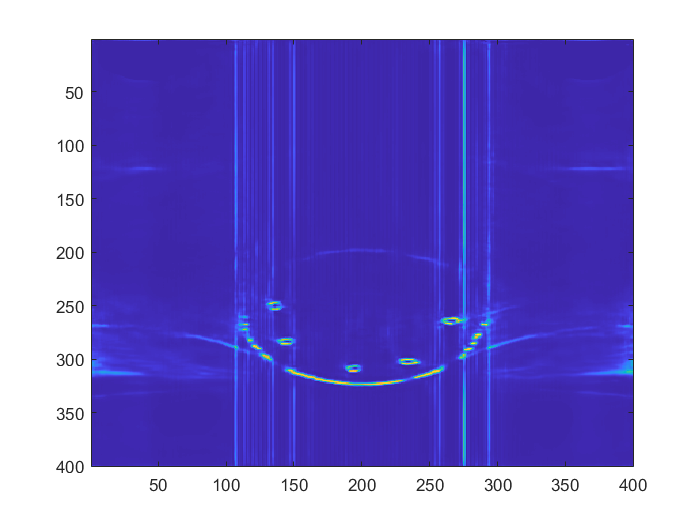

imagesc(output)

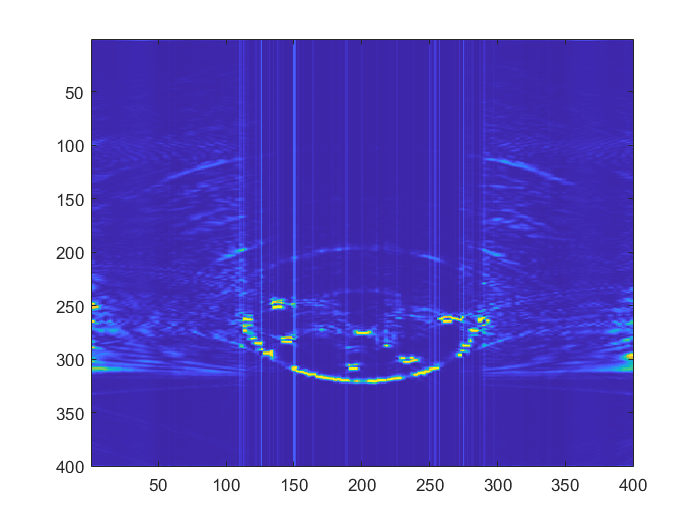

imagesc(normalize(x(:,:,2200),'range',[0 1]))

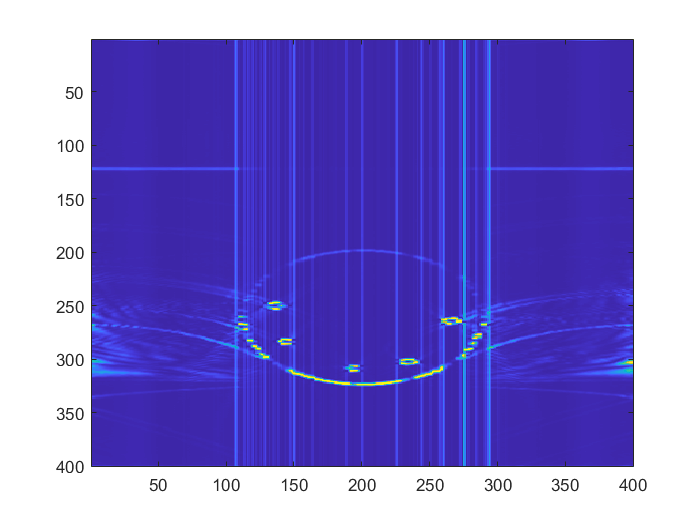

imagesc(normalize(y(:,:,2200),'range',[0 1]))